#                          Face Recognition using Principal Component Analysis

# 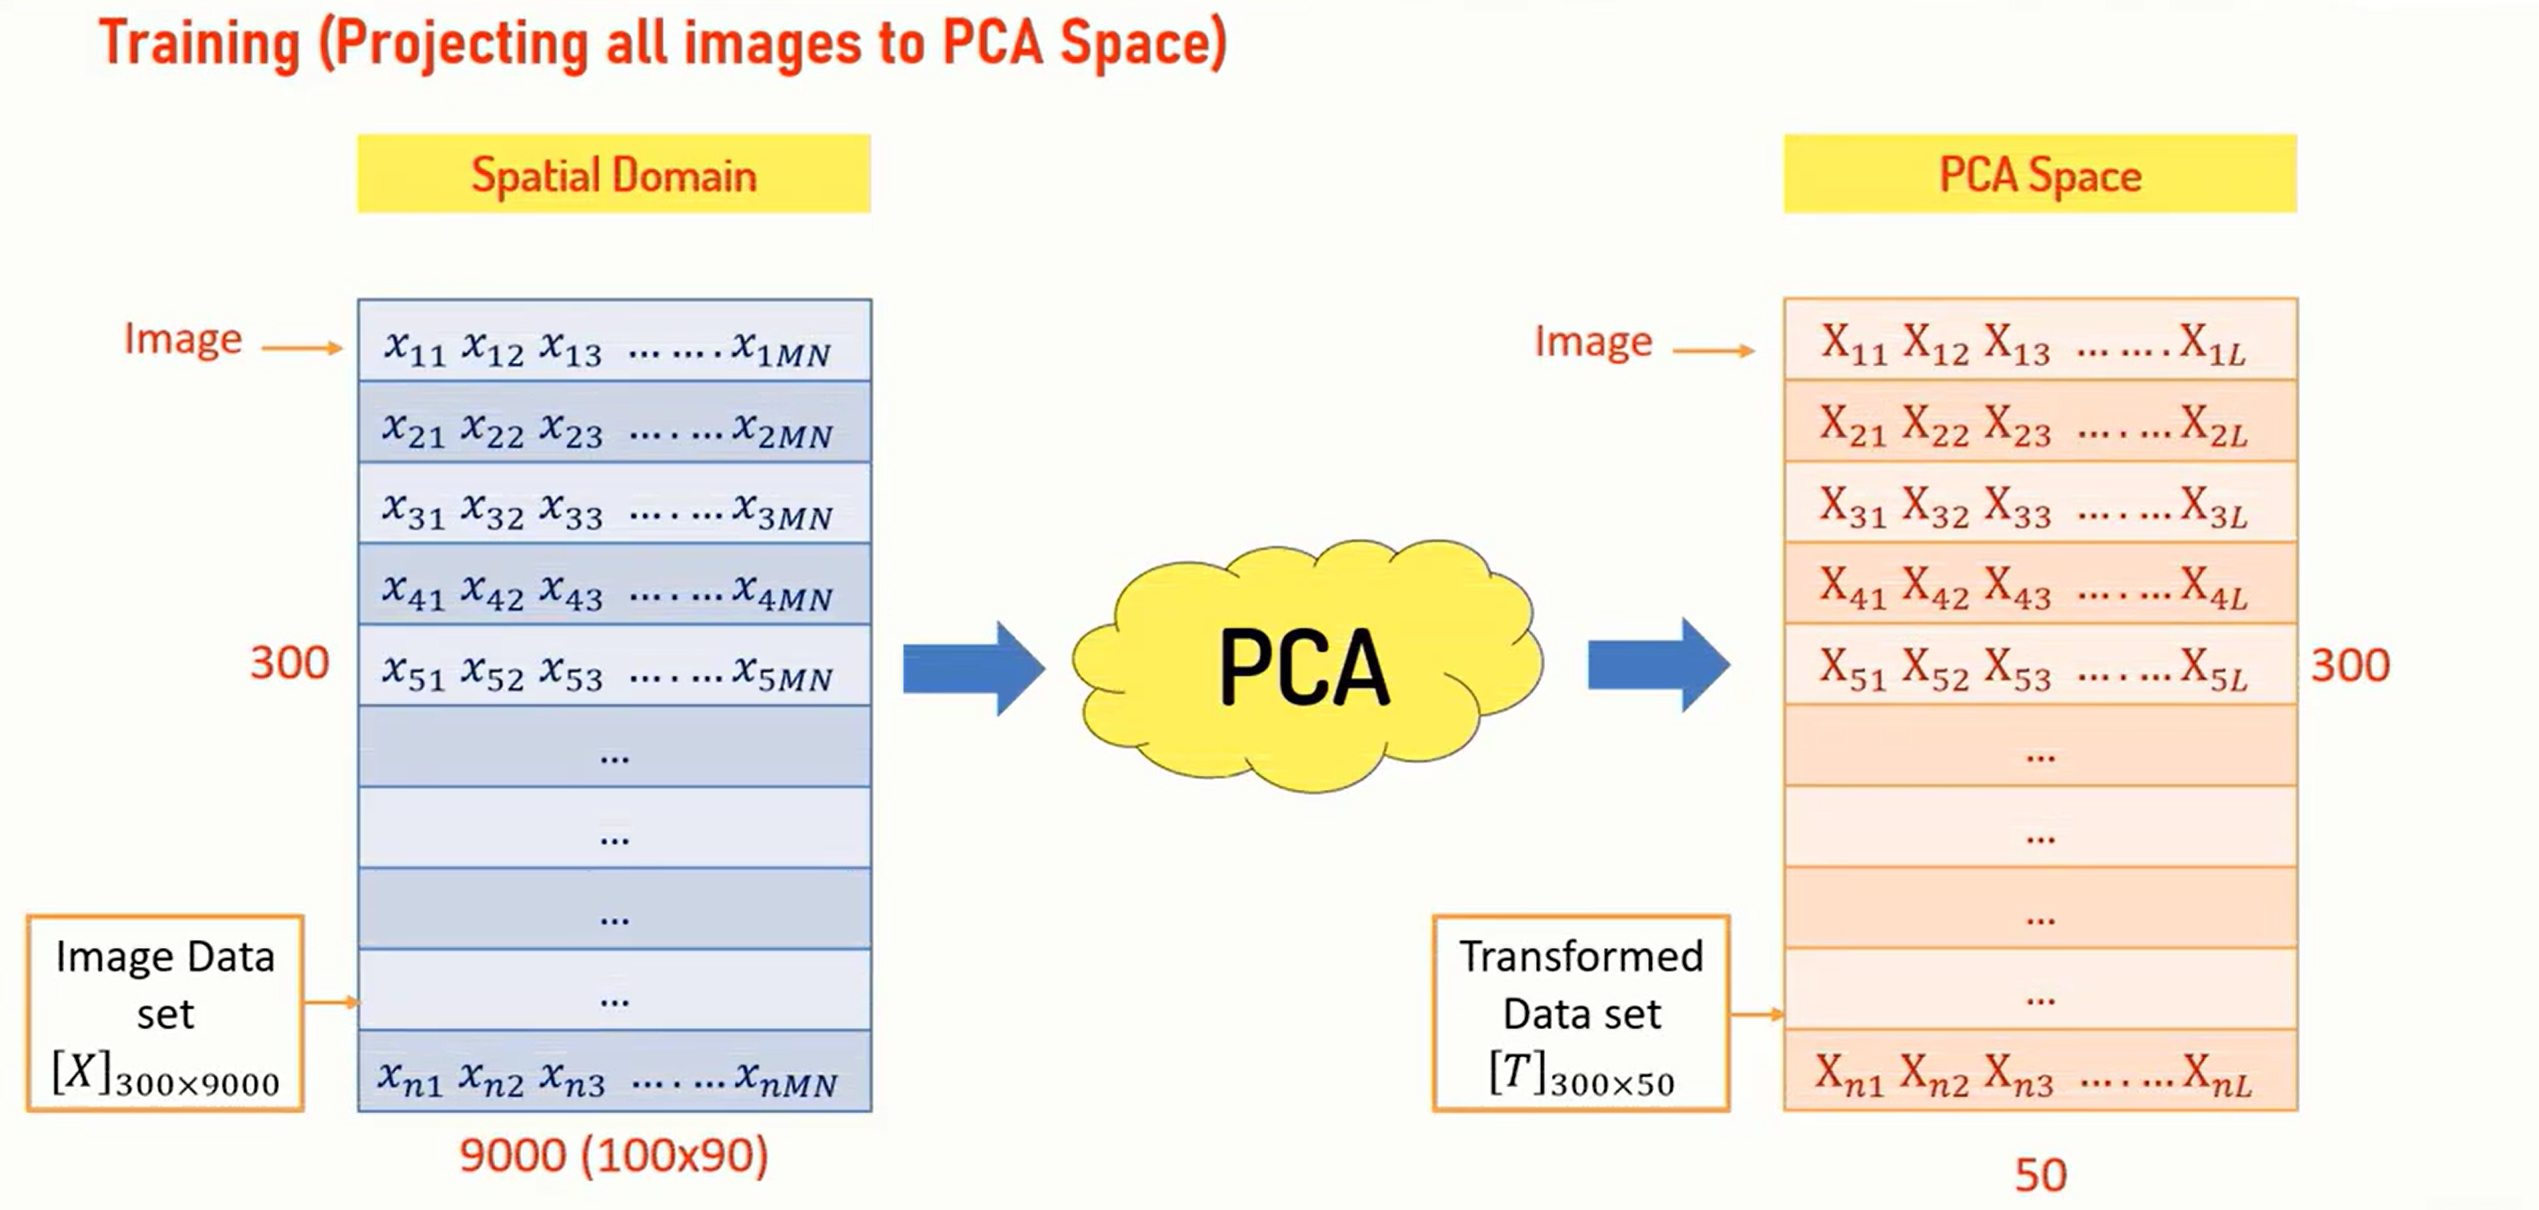

% User inputs for number of images and number of eigenvalues
n = input('Enter the number of images for training: '); % Number of training images
L = input('Enter the number of dominant eigenvalues to keep: '); % Number of eigenvalues to retai

% Dimensions of the images
M = 100; % Height of the images
N = 90;  % Width of the images

% Initialize matrices
X = zeros(n, M * N); % Matrix to hold the flattened images
T = zeros(n, L); % Matrix to hold the PCA-transformed data

% Read and process each image
for count = 1:n
    % Read the image and convert to grayscale
    I = imread(sprintf('%d.jpg', count)); % Assume images are named 1.jpg, 2.jpg, etc.
    I = rgb2gray(I); % Convert to grayscale
    I = imresize(I, [M, N]); % Resize the image to MxN
    
    % Flatten the image and store it in the matrix
    X(count, :) = reshape(I, [1, M * N]);
end

Xb = X; % Store the original data for later use
m = mean(X); % Calculate the mean image across all training images

% Center the data by subtracting the mean
for i = 1:n
    X(i, :) = X(i, :) - m; % Subtract the mean image from each training image
end  

% Compute the covariance matrix
Q = (X' * X) / (n - 1); % Covariance matrix of the centered data

% Perform eigen decomposition
[Evecm, evalm] = eig(Q); % Evecm: eigenvectors, evalm: eigenvalues
Eval = diag(evalm); % Convert eigenvalues to a vector

% Sort eigenvalues in descending order and get the corresponding eigenvectors
[Evalsorted, Index] = sort(Eval, 'descend'); % Sort eigenvalues
Evecsorted = Evecm(:, Index); % Sort eigenvectors based on sorted indices

% Select the top L eigenvectors for PCA
Ppca = Evecsorted(:, 1:L); % Keep only the top L eigenvectors

% Project the original images into PCA space
for i = 1:n
    T(i, :) = (Xb(i, :) - m) * Ppca; % Project each centered image onto the PCA basis
end

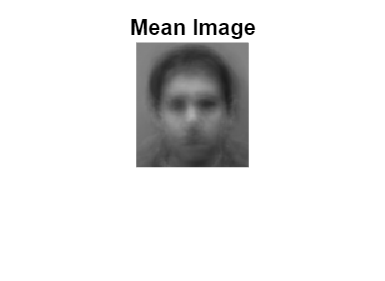

%  display the mean image
mean_image = reshape(m, [M, N]); % Reshape the mean vector to the original image dimensions
imshow(uint8(mean_image)); % Display the mean image, converting to uint8 for visualization
title('Mean Image'); % Add a title to the displayed mean image